# Automate Ground Truth Labeling for Semantic Segmentation

This example shows how to use a pretrained semantic segmentation algorithm to segment the sky and road in an image, and use this algorithm to automate ground truth labeling in the [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app.

## The Ground Truth Labeler App

Good ground truth data is crucial for developing automated driving algorithms and evaluating their performance. However, creating and maintaining a diverse and high-quality set of annotated driving data requires significant effort. The [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app makes this process easy and efficient. This app includes features to annotate objects as rectangles, lines, or pixel labels. Pixel labeling is a process in which each pixel in an image is assigned a class or category, which can then be used to train a pixel-level segmentation algorithm. Although you can use the app to manually label all your data, this process requires a significant amount of time and resources, especially for pixel labeling. As an alternative, the app also provides a framework to incorporate algorithms to extend and automate the labeling process. You can use the algorithms you create to automatically label entire data sets, and then end with a more efficient, shorter manual verification step. You can also edit the results of the automation step to account for challenging scenarios that the algorithm might have missed.

In this example, you will:

- Use a pretrained segmentation algorithm to segment pixels that belong to the categories 'Road' and 'Sky'.

- Create an automation algorithm that can be used in the Ground Truth Labeler app to automatically label road and sky pixels.

This ground truth data can then be used to train a new semantic segmentation network, or retrain an existing one.

## Create a Road and Sky Detection Algorithm

First, create a semantic segmentation algorithm that segments road and sky pixels in an image. The [Semantic Segmentation Using Deep Learning](docid:vision_ug#mw_c671533a-9d94-4d6a-bef0-2982e5d45318) example describes how to train a deep learning network for semantic segmentation. This network has been trained to predict 11 classes of semantic labels including 'Road' and 'Sky'. The performance of these networks depends on how generalizable they are. Applying the networks to situations they did not encounter during training can lead to subpar results. Iteratively introducing custom training data to the learning process can make the network perform better on similar data sets.

Download a network, which was pretrained on the [CamVid dataset [1][2]](https://mi.eng.cam.ac.uk/research/projects/VideoRec/CamVid/) from the University of Cambridge.

pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/segnetVGG16CamVid.mat';
pretrainedFolder = fullfile('.','pretrainedNetwork');
pretrainedSegNet = fullfile(pretrainedFolder,'segnetVGG16CamVid.mat');
if ~exist(pretrainedSegNet,'file')
    if ~exist(pretrainedFolder,'dir')
        mkdir(pretrainedFolder);
    end
    disp('Downloading pretrained SegNet (107 MB)...');
    websave(pretrainedSegNet,pretrainedURL);
end

Segment an image and display it.

% Load the semantic segmentation network
data = load(pretrainedSegNet);

% Load a test image from drivingdata
roadSequenceData = fullfile(toolboxdir('driving'), 'drivingdata', 'roadSequence');
I = imread(fullfile(roadSequenceData, 'f00000.png'));

% Run the network on the image
automatedLabels = semanticseg(I, data.net);

% Display the labels overlaid on the image, choosing relevant categories
figure, imshow(labeloverlay(I, automatedLabels, 'IncludedLabels', ["Sky", "Road"]));

The output of the network is represented in MATLAB® as a categorical matrix. The categories listed include all those that the semantic segmentation network has been trained on, not just the categories present in the output. This information is also available from the network object itself.

% List categories of pixels labeled
categories(automatedLabels)

% The blue overlay indicates the 'Sky' category, and the green overlay
% indicates 'Road'.

## Review the Pixel Segmentation Automation Class

Incorporate this semantic segmentation algorithm into the automation workflow of the app by creating a class that inherits from the abstract base class [`vision.labeler.AutomationAlgorithm`](docid:vision_ref#bvk0cv0-1). This base class defines the API that the app uses to configure and run the algorithm. The Ground Truth Labeler app provides a convenient way to obtain an initial automation class template. For details, see [Create Automation Algorithm for Labeling](docid:vision_ug#mw_6502f53f-e66e-4aaa-bf73-34a8d84284c5). The [`RoadAndSkySegmentation`](matlab:openExample('driving/AutomateGroundTruthLabelingForSemanticSegmentationExample','supportingFile','RoadAndSkySegmentation.m')) class is based on this template and provides a ready-to-use automation class for pixel label segmentation.

The first set of properties in the `RoadAndSkySegmentation` class specify the name of the algorithm, provide a brief description of it, and give directions for using it.

The next section of the `RoadAndSkySegmentation` class specifies the custom properties needed by the core algorithm. The `PretrainedNetwork` property holds the pretrained network. The `AllCategories` property holds the names of all the categories.

`checkLabelDefinition`, the first method defined in `RoadAndSkySegmentation`, checks that only labels of type `PixelLabel` are enabled for automation. `PixelLabel` is the only type needed for semantic segmentation.

The next set of functions control the execution of the algorithm. The `vision.labeler.AutomationAlgorithm` class includes an interface that contains methods like `'initialize'`, `'run'`, and `'terminate'` for setting up and running the automation with ease. The `initialize` function populates the initial algorithm state based on the existing labels in the app. In the `RoadAndSkySegmentation` class, the `initialize` function has been customized to load the pretrained semantic segmentation network from `tempdir` and save it to the `PretrainedNetwork` property.

Next, the `run` function defines the core semantic segmentation algorithm of this automation class. `run` is called for each video frame, and expects the automation class to return a set of labels. The `run` function in [`RoadAndSkySegmentation`](matlab:openExample('driving/AutomateGroundTruthLabelingForSemanticSegmentationExample','supportingFile','RoadAndSkySegmentation.m')) contains the logic introduced previously for creating a categorical matrix of pixel labels corresponding to "Road" and "Sky". This can be extended to any categories the network is trained on, and is restricted to these two for illustration only.

This algorithm does not require any cleanup, so the `terminate` function is empty.

## Use the Pixel Segmentation Automation Class in the App

The properties and methods described in the previous section have been implemented in the [`RoadAndSkySegmentation`](matlab:openExample('driving/AutomateGroundTruthLabelingForSemanticSegmentationExample','supportingFile','RoadAndSkySegmentation.m')) automation algorithm class file. To use this class in the app:

- Create the folder structure `+vision/+labeler` required under the current folder, and copy the automation class into it.

- Open the `groundTruthLabeler` app with custom data to label. For illustration purposes, open the `caltech_cordova1.avi` video.

- On the left pane, click the **Define new ROI label** button and define two ROI labels with names `Road` and `Sky`, of type `Pixel label` as shown.

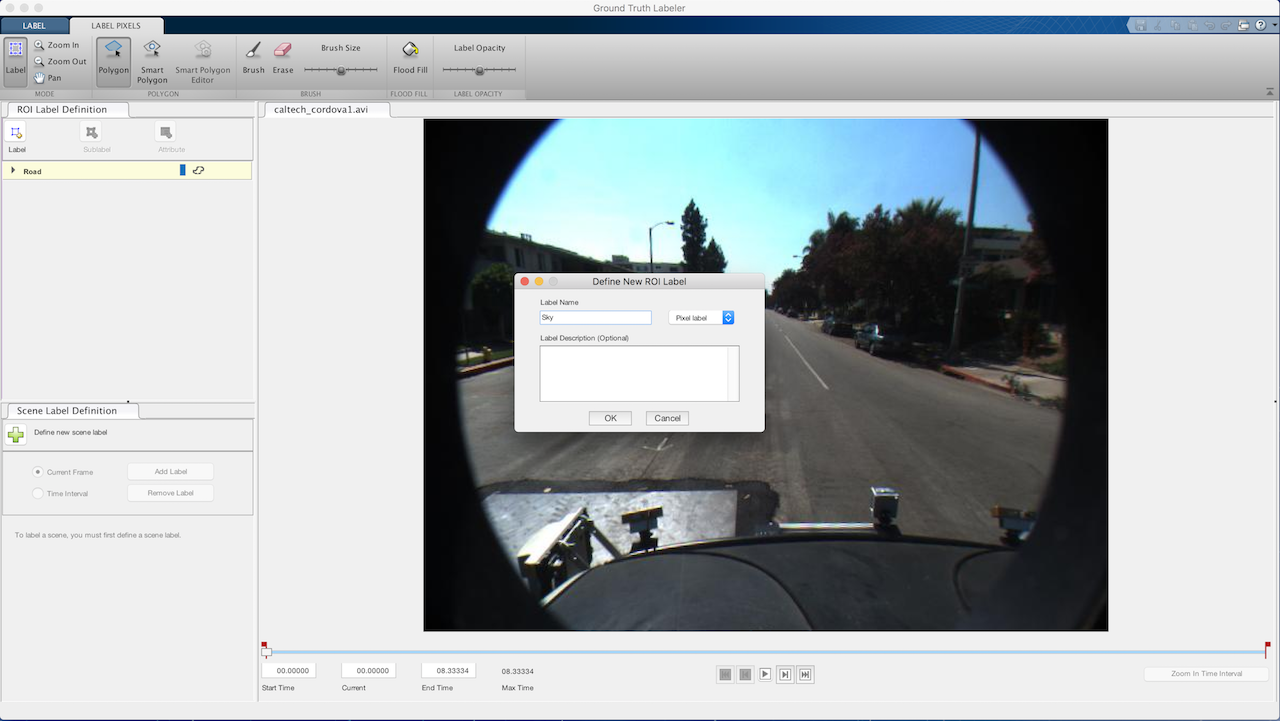

- Click  **Algorithm > Select Algorithm > Refresh list**.

- Click  **Algorithm > RoadAndSkySegmentation**. If you do not see this option, ensure that the current working folder has a folder called `+vision/+labeler`, with a file named `RoadAndSkySegmentation.m` in it.

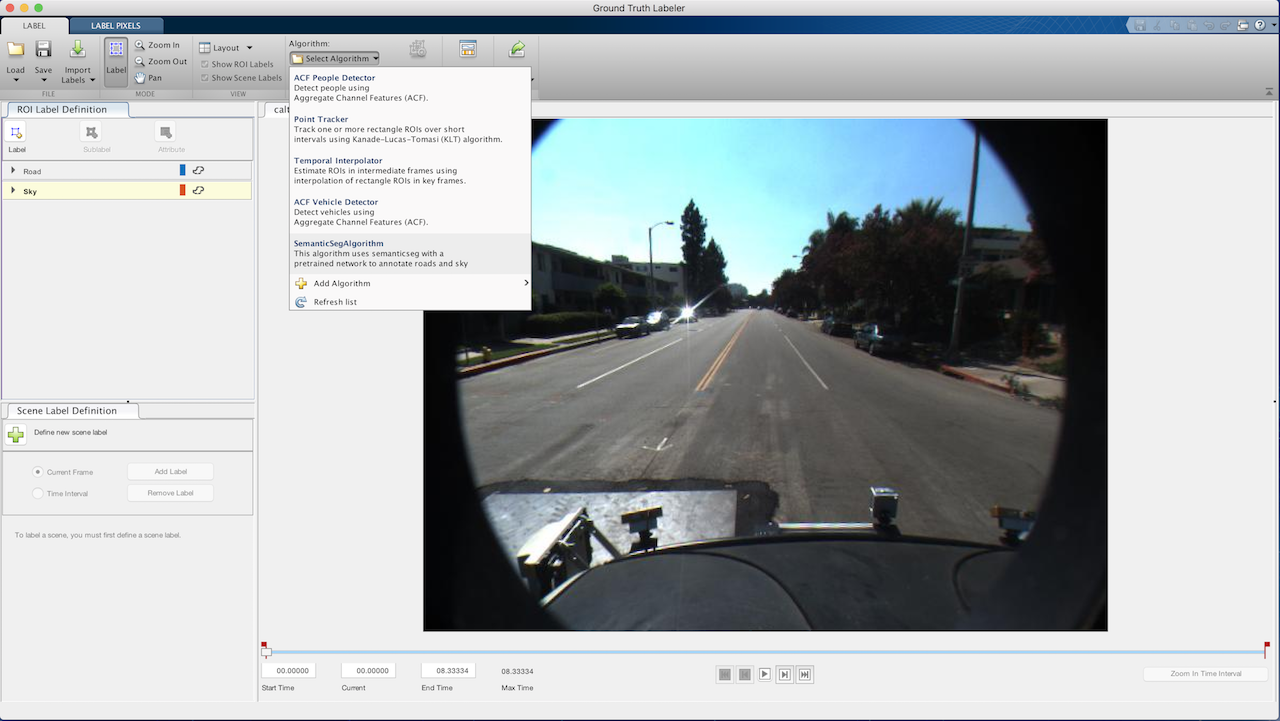

- Click **Automate**. A new panel opens, displaying directions for using the algorithm.

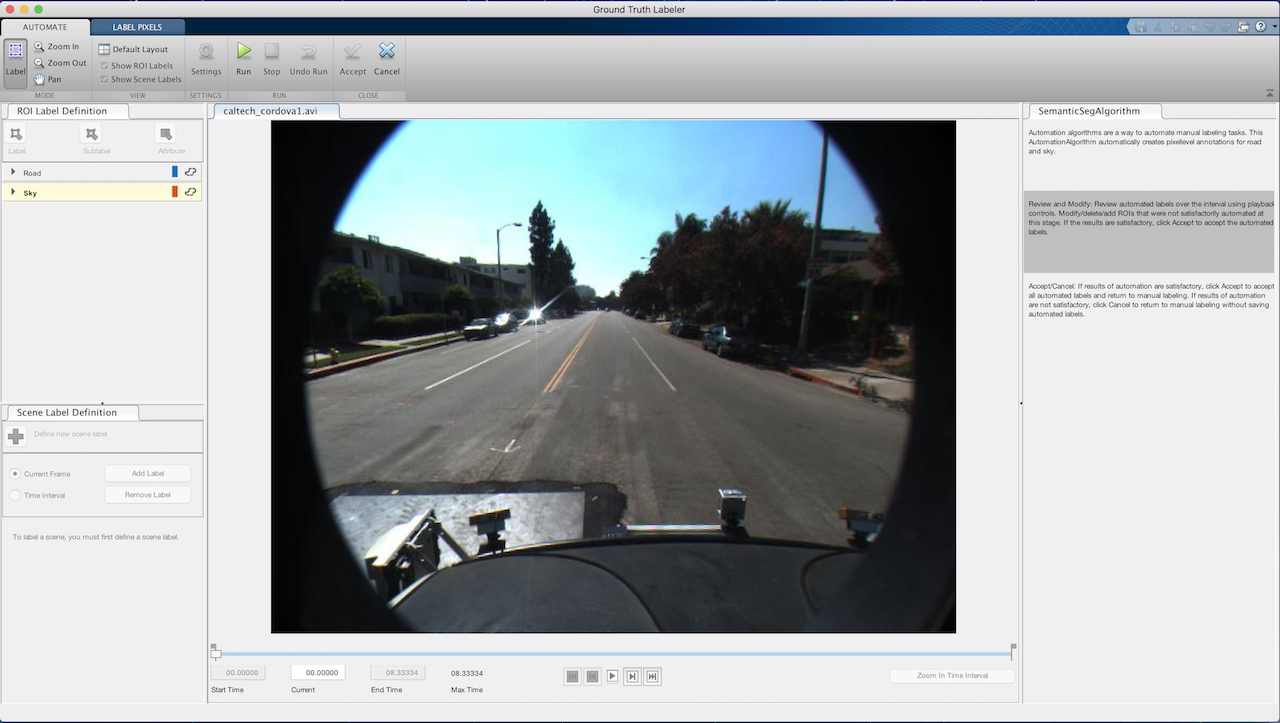

- Click **Run**. The created algorithm executes on each frame of the video, segmenting "Road" and "Sky" categories. After the run is completed, use the slider or arrow keys to scroll through the video and verify the result of the automation algorithm.

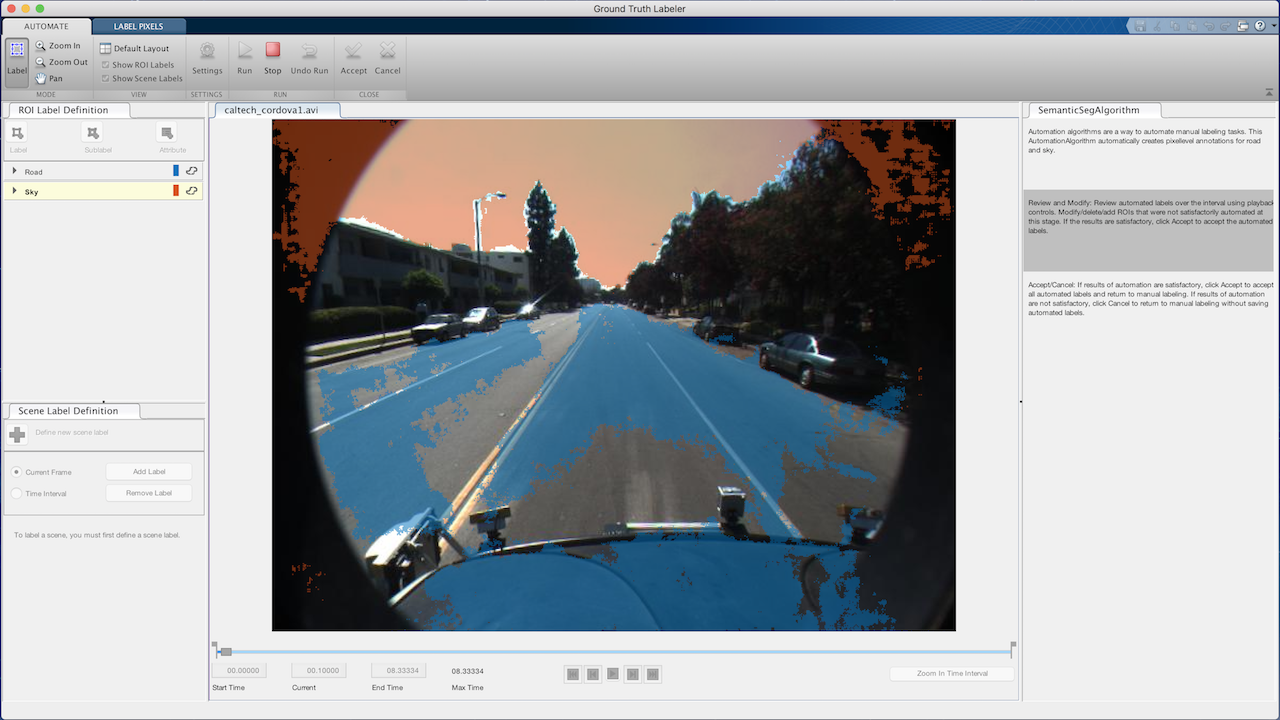

- It is evident that regions outside the camera field of view are incorrectly labeled as "Sky", and parts of the ego vehicle itself are marked as "Road". These results indicate that the network has not been previously trained on such data. This workflow allows for making manual corrections to these results, so that an iterative process of training and labeling (sometimes called *active learning* or *human in the loop* ) can be used to further refine the accuracy of the network on custom data sets. You can manually tweak the results by using the brush tool in the **Label Pixels** tab and adding or removing pixel annotations. Other tools like flood fill and smart polygons are also available in the **Label Pixels** tab and can be used when appropriate.

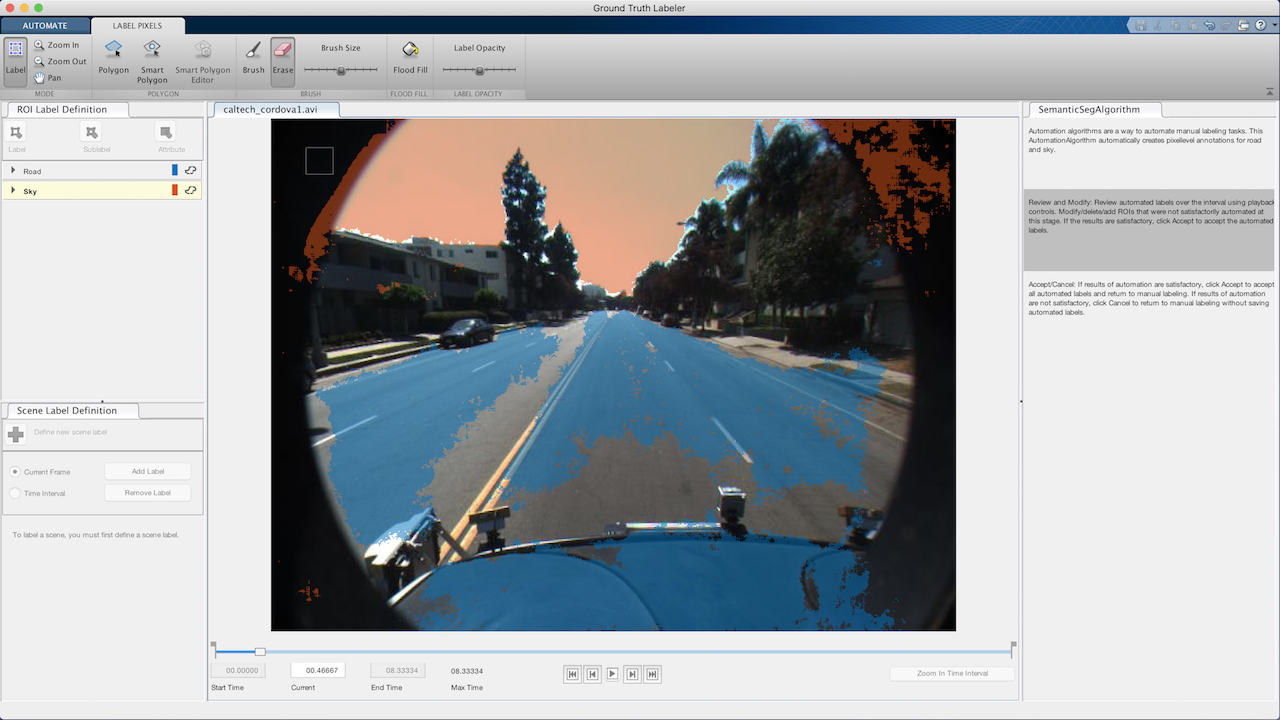

- Once you are satisfied with the pixel label categories for the entire video, click **Accept**.

Automation for pixel labeling for the video is complete. You can now proceed with labeling other objects of interest, save the session, or export the results of this labeling run.

## Conclusion

This example showed how to use a pretrained semantic segmentation network to accelerate labeling of road and sky pixels in the Ground Truth Labeler app using the `AutomationAlgorithm` interface.

## References

- Brostow, Gabriel J., Jamie Shotton, Julien Fauqueur, and Roberto Cipolla. "Segmentation and Recognition Using Structure from Motion Point Clouds." *ECCV*. 2008.

- Brostow, Gabriel J., Julien Fauqueur, and Roberto Cipolla. "Semantic Object Classes in Video: A High-Definition Ground Truth Database." *Pattern Recognition Letters*. 2008.

*Copyright 2018 The MathWorks, Inc.*